# Practice Multiple Regression

[⇦ Multiple Regression](matlab:open('./MultipleRegression.mlx'))

After learning the principles of [multiple regression](matlab:open('./MultipleRegression.mlx')), this exercise allows you to demonstrate your understanding through practical applications in MATLAB.

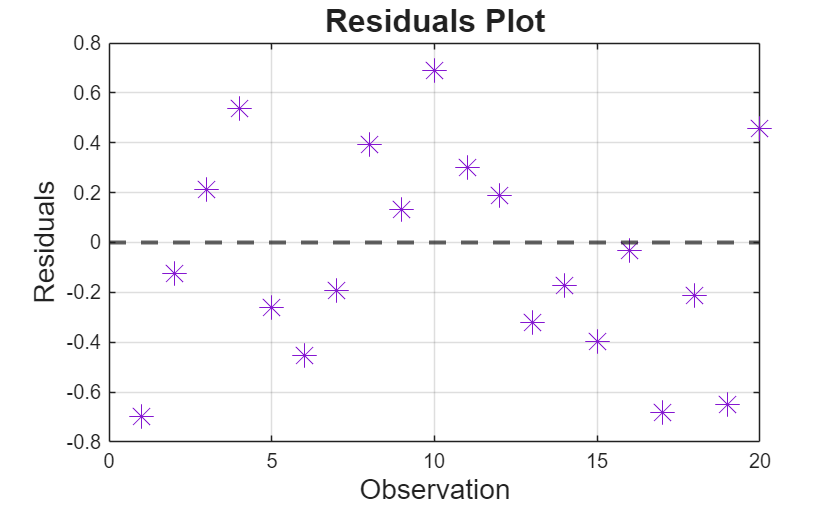

Learn and apply the multiple regression workflow below. 

**Before you get started:**

This live script is intended to be used with the code visible and output inline. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output Inline **using the icon   at the top right of the Live Editor pane.

 Interacting with this live script will build some familiarity with MATLAB as concepts and commands are introduced together. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

  For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections, and they will generate errors if run out of order.

The   and  icons refer to two different types of interactive activities that you will find in this script. The   usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

To run the code, you can click the 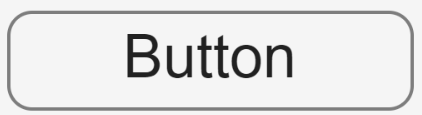**Button** provided, or you can use [image: Run Section icon] **Run Section** or [image: Run and Advance icon] **Run and Advance** in the Live Editor tab of the tool strip, or the equivalent keyboard commands of Ctrl-Enter to run a section or Ctrl-Shift-Enter to run and advance.

## Perform Multiple Regression Step-By-Step

In this lesson, we will begin by generating an artificial dataset to use for analysis. Next, we will create scatter plots comparing the response variable to each predictor variable; these visualizations will help us evaluate whether the relationships appear linear. After assessing these plots and confirming that the linearity assumption is reasonable, we will proceed to fit a multiple linear regression model to the data.

### Generate Dataset

  **Try. **Click the **button** below to generate a randomly generated dataset.

[~,dataset] = GenData1;
 
head(dataset) % Display the first few rows of the dataset

### Fit Linear Regression Model for a Dataset

  **Try. **Click the **button** below to use [`fitlm`](https://www.mathworks.com/help/stats/fitlm.html?s_tid=srchtitle_support_results_1_fitlm) to fit a linear model to the randomly generated dataset and to display the estimated coefficient information.

% Return linear regression model for dataset
mdl = fitlm(dataset,"y~x1+x2+x3") % Fit a linear regression model to the dataset
 

 **Reflect. **Why do linearity checks still matter when p‑values are low, given that p‑values assess the significance of the fitted model but not whether the relationship’s form is appropriate?

### Review ANOVA Summary Statistics for a Dataset

  **Try. **Click the **button** below to use [`fitlm`](https://www.mathworks.com/help/stats/fitlm.html?s_tid=srchtitle_support_results_1_fitlm) to fit a linear model to the randomly generated dataset and to display the estimated coefficient information.

% Show ANOVA table for the full model mdl
anova(mdl,'summary')
 

 **Reflect. **Based on the model statistics, what information do you gain from going through the linearity assumption checks?

### Check the Linearity Assumption

- **Linearity Assumption:** The relationship between predictors and the response should be roughly linear.

- *Check 1:* Scatter plots of the response vs. each predictor should show an approximately straight-line pattern.

- *Check 2: *Residual plots should not display any clear patterns

#### Preliminary Visual Assessment Using Scatter Plots

  **Exercise 1**.The code for fitting the first predictor vs. the response is shown below. Repeat this form for each of the 2 remaining predictors replacing the 1 with 2, and 3 respectively.

% Fit a linear regression model for Predictor1
mdl1 = fitlm(dataset,"y ~ x1");

% Plot the linear regression model
figure
plot(mdl1)
xlabel("Predictor 1")
ylabel("Response")
title("Scatter Plot of Predictor1 vs Response")

% Enter your code here.
% Fit a linear regression model for Predictor2

% Plot the linear regression model
% Fit a linear regression model for Predictor3

% Plot the linear regression model

#### **Linearity Assessment Using the Full Model and Residuals**

  **Try. **Click the **button** to view the residuals plot using [`plotResiduals`](https://www.mathworks.com/help/stats/linearmodel.plotresiduals.html?s_tid=srchtitle_support_results_1_plotResiduals).

% Plot the residuals of the full model mdl
figure
plotResiduals(mdl,"fitted")
xlabel("Fitted Values")
ylabel("Residual")
title("Residuals vs. Fitted Values")
 
 

### Check the Independence Assumption

- **Independence Assumption:** Residuals (errors) should be independent of each other, with no autocorrelation.

- *Check:* Plot residuals against predicted values (fitted values) in sequence and look for unusual patterns or clustering in residual plots.

  **Try. **Click the **button** below to make the sequenced fitted residuals plot using [`plotResiduals`](https://www.mathworks.com/help/stats/linearmodel.plotresiduals.html?s_tid=srchtitle_support_results_1_plotResiduals).

% Plot the residuals against the case order
plotResiduals(mdl,"caseorder")
 

### Check the Equal Variance Assumption 

- **Equal Variance (Homoscedasticity):** Residual variance should be constant across fitted values.

- *Check:* Residuals vs. any of the predictors or the fitted values should show a consistent spread around the zero line, without fan or cone shapes.

The Residuals plot helps to visualize the distribution of residuals and check for patterns. Ideally, the residuals should be randomly scattered around zero, indicating a good fit.

  **Try. **Click the **button** below to make the fitted residuals plot using [`plotResiduals`](https://www.mathworks.com/help/stats/linearmodel.plotresiduals.html?s_tid=srchtitle_support_results_1_plotResiduals).

% Plot the residuals against the fitted values
plotResiduals(mdl,"fitted")
 

### Check the Normality Assumption

- **Normality Assumption:** Residuals should be approximately normally distributed.

- *Check 1:* Histogram of residuals should resemble a normal distribution. 

- *Check 2:* In a probability plot of the residuals, the plotted points should fall roughly along a straight diagonal line, indicating that the observed residual probabilities are consistent with those expected under a normal distribution.

Two plots commonly used to assess whether residuals follow a normal distribution are the histogram and the probability plot of the residuals. The histogram shows the overall shape of the residuals, and a roughly symmetric, bell‑shaped pattern suggests normality. The probability plot compares the residuals to what would be expected under a normal distribution; if the residuals are normally distributed, the points will lie close to the reference line. Together, these plots help identify departures from normality such as skewness, heavy tails, or outliers.

  **Try. **Click the **button** below to make the residuals histogram and the residuals probability plot using [`plotResiduals`](https://www.mathworks.com/help/stats/linearmodel.plotresiduals.html?s_tid=srchtitle_support_results_1_plotResiduals).

% Plot Residuals Histogram
plotResiduals(mdl,"histogram")

% Plot the Probability Plot of Residuals
plotResiduals(mdl,"probability")
 

 **Reflect**. Does the dataset meet the assumptions of linearity? Is a full multiple regression analysis appropriate?

## Practice Problem 1.

### Generate Dataset

  **Try. **Click the **button** below to generate a randomly generated dataset and display the first 10 rows of data.

beta = [5;2;3]; %#ok<NASGU> % True coefficients for the linear model
[tbl,beta,Y] = GenData2;
 
head(tbl)

### Fit Linear Regression Model for Dataset

  **Exercise 2a**. Enter code in the code block below to return the linear regression model (`mdl)` for '`tbl`'.

  **Pro-tip**. Note that the variable names use uppercase letters.

% Enter your code below
% Return linear regression model for dataset
mdl=fitlm(tbl,"Y~X1+X2")

 **Reflect. **Why do linearity checks still matter if the p‑values are low, given that p‑values assess the significance of the fitted model but not whether the relationship’s form is appropriate?

### Review ANOVA Summary Statistics for a Dataset

  **Exercise 2b**. Enter code in the code block below to display the summary statistics for the linear regression model (`mdl)` for '`tbl`'.

% Show ANOVA table for the full model mdl
anova(mdl,"summary")

 **Reflect. **Based on the model statistics, what information do you gain from going through the linearity assumption checks?

### Check the Linearity Assumption

- **Linearity Assumption:** The relationship between predictors and the response should be roughly linear.

- *Check 1:* Scatter plots of the response vs. each predictor should show an approximately straight-line pattern.

- *Check 2: *Residual plots should not display any clear patterns. 

#### Preliminary Visual Assessment Using Scatter Plots

  **Exercise 2c**. Enter the code above to check each predictor vs. the response to ensure linearity. Label the regression models, `md1` and `mdl2` for the two predictors.

% Enter your code below
% Fit a linear regression model for Predictor1
% Fit a linear regression model for Predictor2


#### **Linearity Assessment Using the Full Model and Residuals**

  **Exercise 2d**. Enter the code to make the residuals plot.

% Enter your code below
% Fit a linear regression model for the full model

### Check the Independence Assumption 

- **Independence Assumption:** Residuals (errors) should be independent of each other, with no autocorrelation.

- *Check:* Plot residuals against fitted values in sequence and look for unusual patterns or clustering in residual plots.

  **Exercise 2e**. Enter the code to make the sequenced fitted residuals plot.

% Enter your code below
% Plot the residuals against the fitted values

### Check the Equal Variance Assumption 

- **Equal Variance (Homoscedasticity):** Residual variance should be constant across fitted values.

- *Check:* Residuals vs. any of the predictors or the fitted values should show a consistent spread around the zero line, without fan or cone shapes.

  **Exercise 2f**. Enter the code below to make the fitted residuals plot. 

% Enter your code below
% Plot the residuals against the fitted values

### Check the Normality Assumption

- **Normality Assumption:** Residuals should be approximately normally distributed.

- *Check 1:* Histogram of residuals should resemble a normal distribution. 

- *Check 2:* In a probability plot of the residuals, the plotted points should fall roughly along a straight diagonal line, indicating that the observed residual probabilities are consistent with those expected under a normal distribution.

Two plots commonly used to assess whether residuals follow a normal distribution are the histogram and the probability plot of the residuals. The histogram shows the overall shape of the residuals, and a roughly symmetric, bell‑shaped pattern suggests normality. The probability plot compares the residuals to what would be expected under a normal distribution; if the residuals are normally distributed, the points will lie close to the reference line. Together, these plots help identify departures from normality such as skewness, heavy tails, or outliers.

  **Exercise 2g**. Enter the code below to make the residuals histogram and the residuals probability plot. 

% Enter your code below
% Plot Residuals Histogram

% Plot the Probability Plot of Residuals

 **Reflect**. Does the dataset meet the assumptions of linearity? Is a full multiple regression analysis appropriate?

** Application. **

## Practice Problem 2. DC Power Consumption

Modern telecom and data‑center equipment is powered by DC supplies. Engineers often want a **simple, interpretable model** that predicts **DC power consumption** from operational variables for capacity planning and energy audits.

In this problem, you will analyze measured (synthetic) data from a DC‑powered system and determine:

- Whether the **linearity assumptions** of multiple linear regression are reasonable

- Whether a **multiple linear regression model** is appropriate

- How to interpret the fitted coefficients physically

**System description:**

The system consists of DC‑powered telecom equipment operating under varying load conditions.

**Measured variables**

### Generate Dataset

  **Try. **Click the **button** below to load the data into a table.

% Load DCPowerData.mat into a table
load DCPowerData.mat TrafficLoad ActiveModules AmbientTemp DCPower
Tbl = table(TrafficLoad,ActiveModules,AmbientTemp,DCPower,VariableNames={'TrafficLoad','ActiveModules', 'AmbientTemp','DCPower'})
 

### Fit Linear Regression Model for Dataset

  **Exercise 3a**. Enter code in the code block below to return the linear regression model (`mdl)` for 'T`bl`'.

% Enter your code below
% Return linear regression model for dataset
mdl=fitlm(Tbl,"DCPower~TrafficLoad+ActiveModules+AmbientTemp")

 **Reflect. **Why do linearity checks still matter if the p‑values are low, given that p‑values assess the significance of the fitted model but not whether the relationship’s form is appropriate?

### Review ANOVA Summary Statistics for a Dataset

  **Exercise 3b**. Enter code in the code block below to display the summary statistics for the linear regression model (`mdl)` for 'T`bl`'.

% Show ANOVA table for the full model mdl
anova(mdl,"summary")

 **Reflect. **Based on the model statistics, what information do you gain from going through the linearity assumption checks?

### Check the Linearity Assumption

- **Linearity Assumption:** The relationship between predictors and the response should be roughly linear.

- *Check 1:* Scatter plots of the response vs. each predictor should show an approximately straight-line pattern.

- *Check 2: *Residual plots should not display any clear patterns

#### Preliminary Visual Assessment Using Scatter Plots

  **Exercise 3c**. Enter the code above to check each predictor vs. the response to ensure linearity. Repeat this form for the 2 predictors, replacing the 1 with 2.

% Enter your code below
% Fit a linear regression model for Predictor1


% Fit a linear regression model for Predictor2


% Fit a linear regression model for Predictor3

#### **Linearity Assessment Using the Full Model and Residuals**

 **Exercise 3d. **Enter code to plot the residuals plot.

% Enter your code below
% Fit a linear regression model for the full model

### Check the Independence Assumption 

- **Independence Assumption:** Residuals (errors) should be independent of each other, with no autocorrelation.

- *Check:* Plot residuals against predicted values (fitted values) in sequence and look for unusual patterns or clustering in residual plots.

  **Exercise 3e**. Enter the code to make the sequenced fitted residuals plot.

% Enter your code below
% Plot the residuals against the fitted values

### Check the Equal Variance Assumption 

- **Equal Variance (Homoscedasticity):** Residual variance should be constant across fitted values.

- *Check:* Residuals vs. any of the predictors or the fitted values should show a consistent spread around the zero line, without fan or cone shapes.

  **Exercise 3f**. Enter the code below to make the fitted residuals plot. 

% Enter your code below
% Plot the residuals against the fitted values

### Check the Normality Assumption

- **Normality Assumption:** Residuals should be approximately normally distributed.

- *Check 1:* Histogram of residuals should resemble a normal distribution. 

- *Check 2:* In a probability plot of the residuals, the plotted points should fall roughly along a straight diagonal line, indicating that the observed residual probabilities are consistent with those expected under a normal distribution.

Two plots commonly used to assess whether residuals follow a normal distribution are the histogram and the probability plot of the residuals. The histogram shows the overall shape of the residuals, and a roughly symmetric, bell‑shaped pattern suggests normality. The probability plot compares the residuals to what would be expected under a normal distribution; if the residuals are normally distributed, the points will lie close to the reference line. Together, these plots help identify departures from normality such as skewness, heavy tails, or outliers.

  **Exercise 3g**. Enter the code below to make the residuals histogram and the residuals probability plot. 

% Enter your code below
% Plot Residuals Histogram

% Plot the Probability Plot of Residuals

 **Reflect**. Does the dataset meet the assumptions of linearity? Is a full multiple regression analysis appropriate?

[⇦ Return to the Multiple Regression](matlab:open('./MultipleRegression.mlx'))

## Local Helper Functions

function [Y,dataset] = GenData1
% GenData1 Generate a synthetic linear dataset with three predictors
% Modified to avoid rank-deficient design matrix by ensuring predictors
% are not (nearly) collinear and by adding small independent variation.

% Parameters for the synthetic dataset
numObservations = 100; % Number of observations

% Create predictors with distinct patterns and independent noise
t = linspace(0,1,numObservations)'; % base index
x1 = t + 0.01*randn(numObservations,1); % increasing trend + small noise
x2 = 0.5*sin(2*pi*2*t) + 0.01*randn(numObservations,1); % sinusoidal pattern + small noise
x3 = 0.3*cos(2*pi*3*t) + 0.01*randn(numObservations,1); % different frequency + small noise

% Check and enforce approximate orthogonality (optional small adjustment)
% Remove any linear dependence by orthogonalizing x2 and x3 relative to x1
x2 = x2 - ((x1' * x2) / (x1' * x1)) * x1;
x3 = x3 - ((x1' * x3) / (x1' * x1)) * x1 - ((x2' * x3) / (x2' * x2)) * x2;

% Scale predictors to comparable ranges (improves numeric conditioning)
x1 = (x1 - mean(x1)) / std(x1);
x2 = (x2 - mean(x2)) / std(x2);
x3 = (x3 - mean(x3)) / std(x3);

% True coefficients for the linear model (distinct magnitudes)
trueCoefficients = [2;-1.5;0.5];

% Small independent noise (kept nonzero to avoid exact collinearity)
noise = randn(numObservations,1) * 0.01;

% Construct predictor matrix and response
X = [x1,x2,x3];
Y = X * trueCoefficients + noise;

% Create a table with named columns
dataset = table(x1,x2,x3,Y,VariableNames={'x1','x2','x3','y'});
end

function [tbl,beta,Y] = GenData2
% Function to generate a second artificial dataset
% This function creates a synthetic dataset with two predictor variables (X1,X2)
% and a response variable (Y) based on a linear model with added low-noise,
% more linearly related predictors.

%% Generate synthetic data
n = 120; % Number of observations

% Create predictors with a clear linear structure (use linspace with small jitter)
X1 = linspace(0,10,n)' + 0.01*randn(n,1); % Predictor 1 with minor noise
X2 = linspace(0,10,n)' + 0.01*randn(n,1); % Predictor 2 with minor noise

beta = [5;2;3]; % True coefficients for the linear model
signal = beta(1) + beta(2)*X1 + beta(3)*X2; % Calculate the signal based on the linear model

% Add small noise to make the response closely linear in predictors
noiseStd = 0.05; % Reduced standard deviation of the noise
noise = noiseStd * randn(n,1); % Generate random noise

Y = signal + noise; % Generate the response variable by adding low noise to the signal

%% Organize data in a table
tbl = table(X1,X2,Y,VariableNames={'X1','X2','Y'}); % Combine predictors and response into a table for better visualization
end